# Bifurcation diagram for a Y-shaped quantum graph

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

## Construct the quantum graph and find the first few eigenfunctions

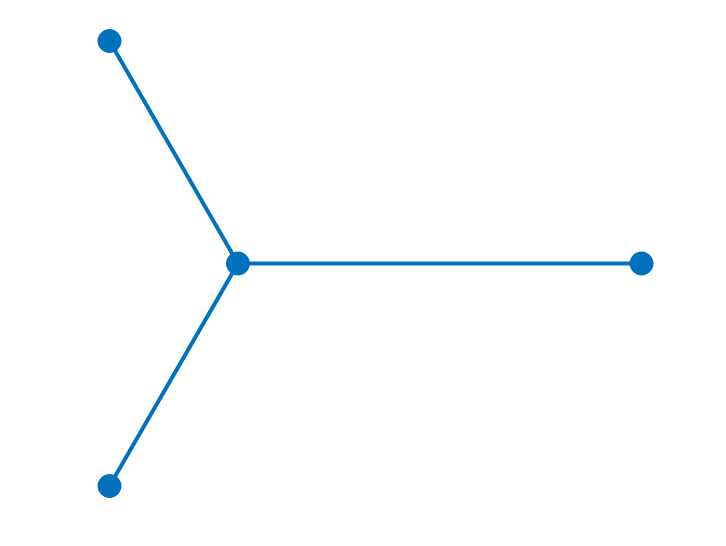

Created directory data/star/010.
Run number is 10.


tag='star';
LVec=[pi/2 1 1]; % Nonresonant lengths chosen to exclude double eigenvalues
Phi = quantumGraphFromTemplate(tag,'LVec',LVec);
dataDir = makeContinuationDirectory(Phi,tag);

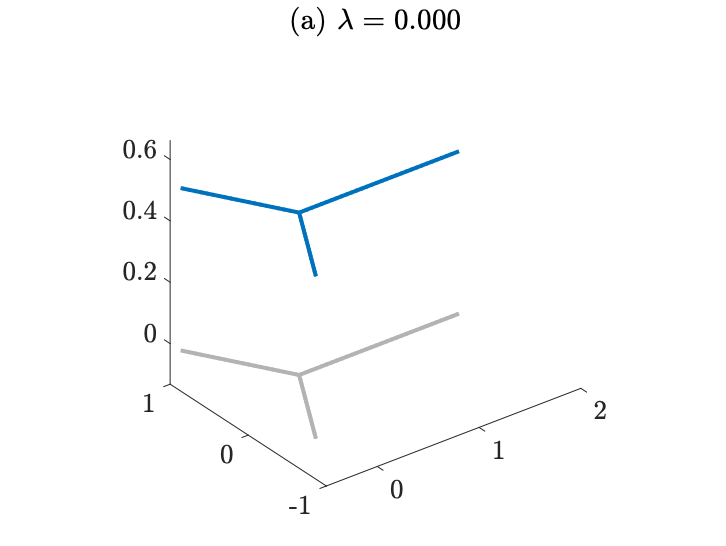

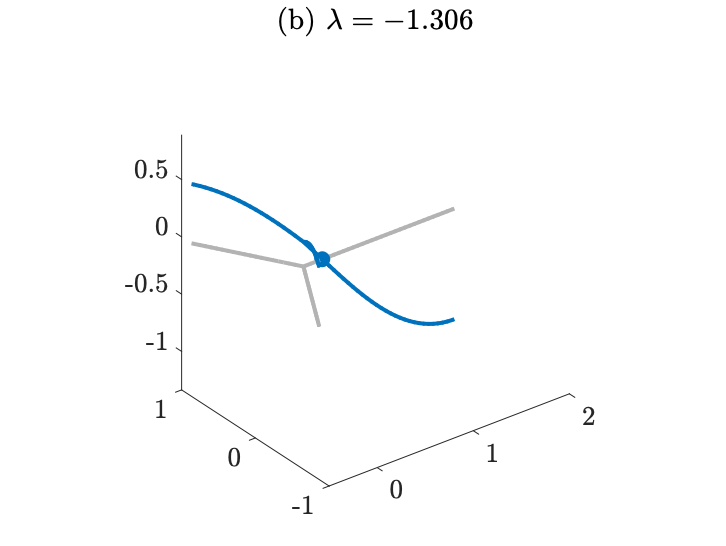

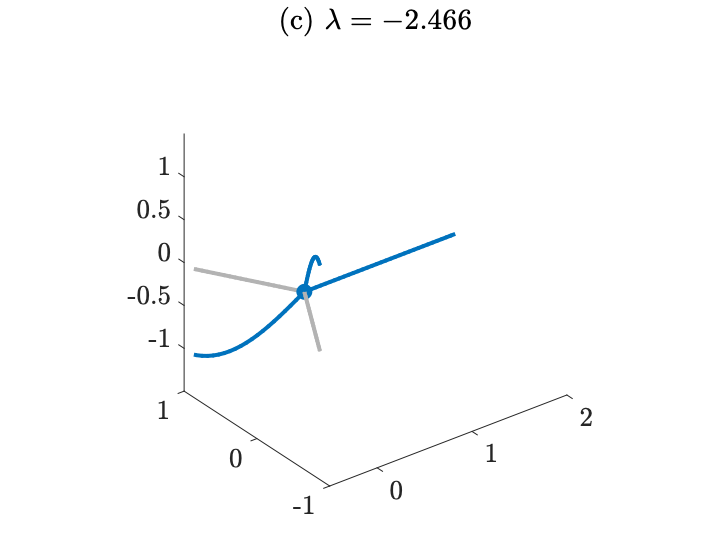

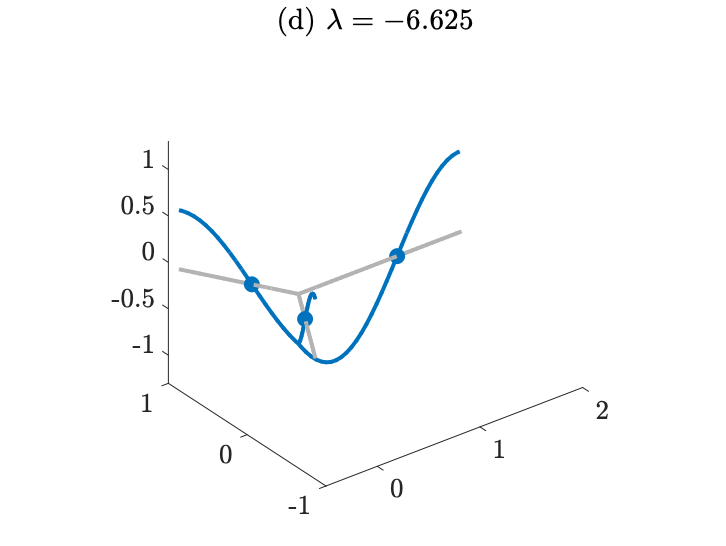

nToPlot=4;
nDoubles=2;
saveEigenfunctions(Phi,tag,dataDir,nToPlot,nDoubles);

fcns = saveNLSFunctionsGraph(dataDir,Phi); % Use the default cubic nonlinearity

## Compute a branch that is a continuation of the ground state eigenfunction

- The function `continuerSet` works like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

The output of `continuefromEig` is `branch1` The branch number

options=continuerSet([],'LambdaThresh',-2,'NThresh',4,'plotFlag',false,'maxTheta',2);
branch1=continueFromEig(dataDir,1,options);

Lambda threshold crossed.
Branch number 1.
Data saved to directory data/star/010/branch001.
Branching Bifurcation at solution number 19.
Branching Bifurcation at solution number 26.


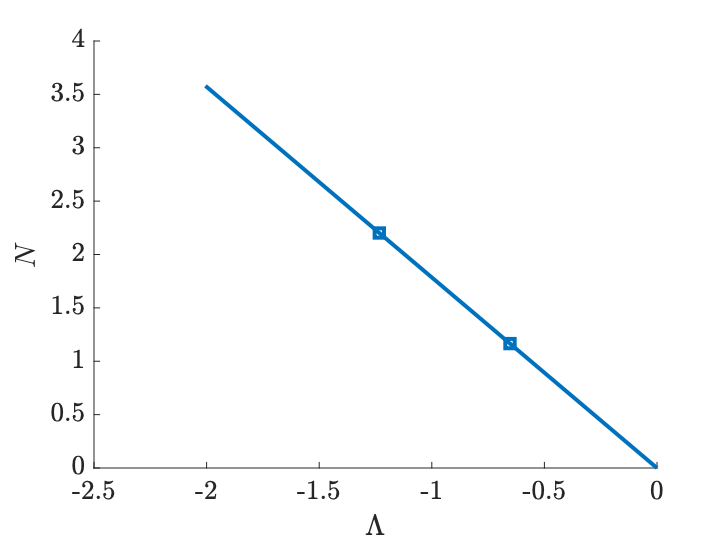

bifurcationDiagram(dataDir)

## Compute some branches that bifurcate from this first branch

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a symmetry-breaking bfirucation, we only need to continue in one direction, the branch stored in branch`3` at bifurcation location 2

branch2=continueFromBranchPoint(dataDir,branch1,1,1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data/star/010/branch002.
No branching bifurcations found.


branch3=continueFromBranchPoint(dataDir,branch1,1,-1,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data/star/010/branch003.
Branching Bifurcation at solution number 14.


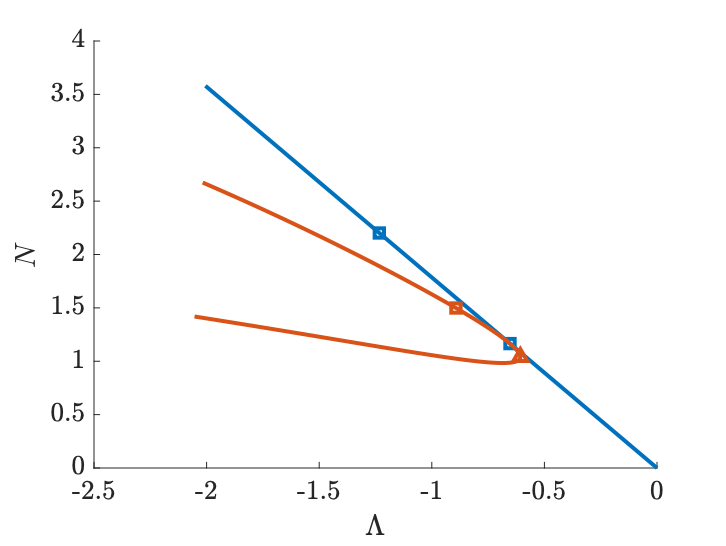

bifurcationDiagram(dataDir)

- The function `continueFromBranchpoint` continues a branch from the second branching bifurcation point. Since this is a pitchfork bifurcation, we need to continue in just one direction, the branch stored in branch`3` at bifurcation location` bl1(2)`

branch4=continueFromBranchPoint(dataDir,branch1,2,1,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data/star/010/branch004.
No branching bifurcations found.


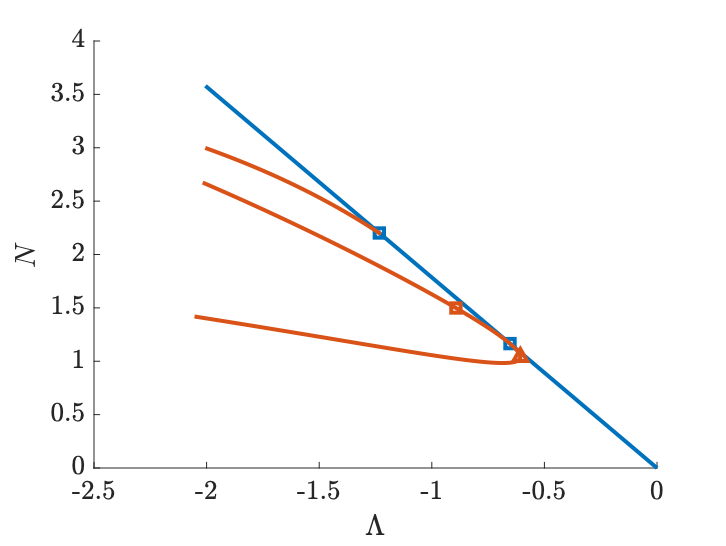

bifurcationDiagram(dataDir)

## Compute a branch that bifurcates from the second branch

Continues from the branch stored in branch`3` from the bifurcation point at `bl3(1)`. This bifurcation breaks the symmetry in branches two and three.

branch5=continueFromBranchPoint(dataDir,branch3,1,1,options);

Lambda threshold crossed.
Branch number 5.
Data saved to directory data/star/010/branch005.
No branching bifurcations found.


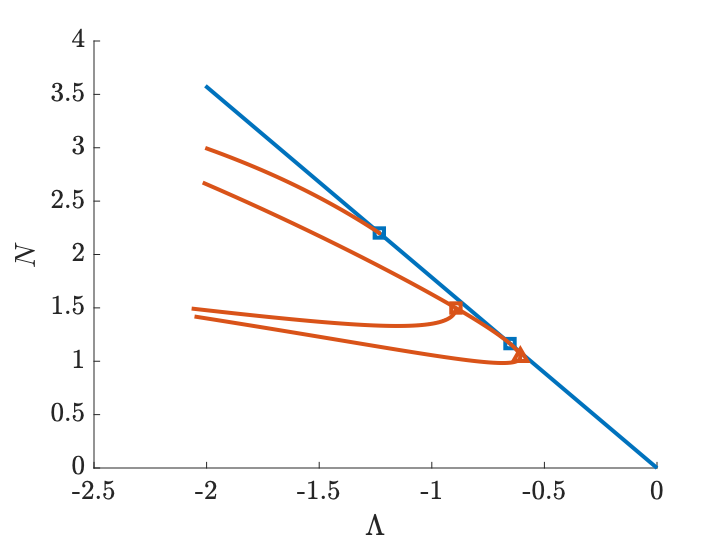

bifurcationDiagram(dataDir)

## Plot some solutions

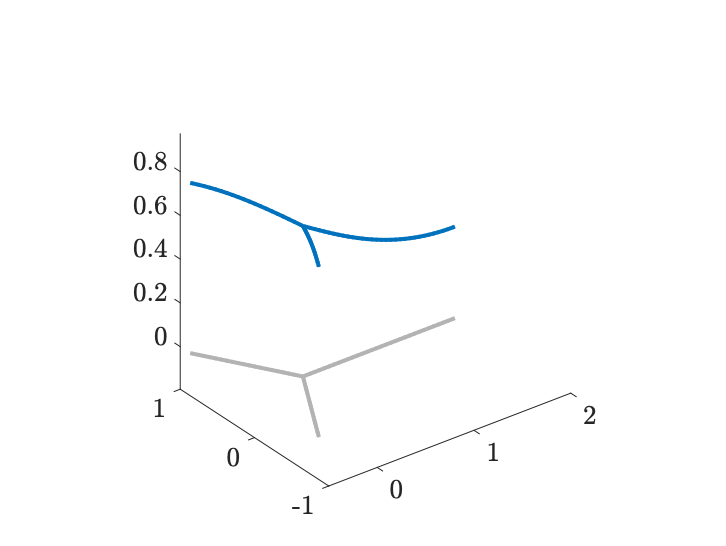

plotSolution(dataDir,branch3,15)

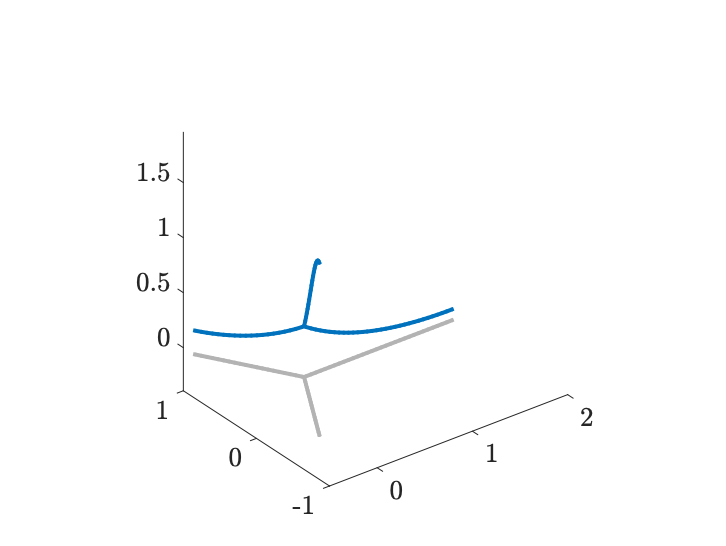

plotSolution(dataDir,branch5,'last')